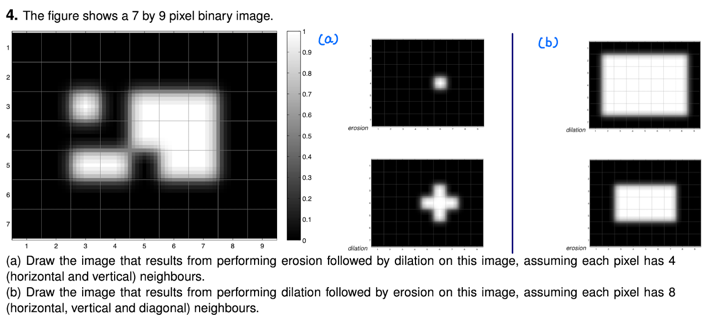

im = [zeros(2,9)
    0 0 1 0 1 1 1 0 0
    0 0 0 0 1 1 1 0 0
    0 0 1 1 0 1 1 0 0
    zeros(2,9)]

im =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     1     0     1     1     1     0     0
     0     0     0     0     1     1     1     0     0
     0     0     1     1     0     1     1     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0



% 4 neighbours
SE_4 = strel("diamond", 1);
erosion_4 = imerode(im, SE_4)

erosion_4 =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


dailation_4 = imdilate(erosion_4, SE_4)

dailation_4 =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0



% 8 neighbours
SE_8 = strel("square",3);
dailation_8 = imdilate(im, SE_8)

dailation_8 =      0     0     0     0     0     0     0     0     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     0     0     0     0     0     0     0     0


erosion_8 = imerode(dailation_8, SE_8)

erosion_8 =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     1     1     1     1     1     0     0
     0     0     1     1     1     1     1     0     0
     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


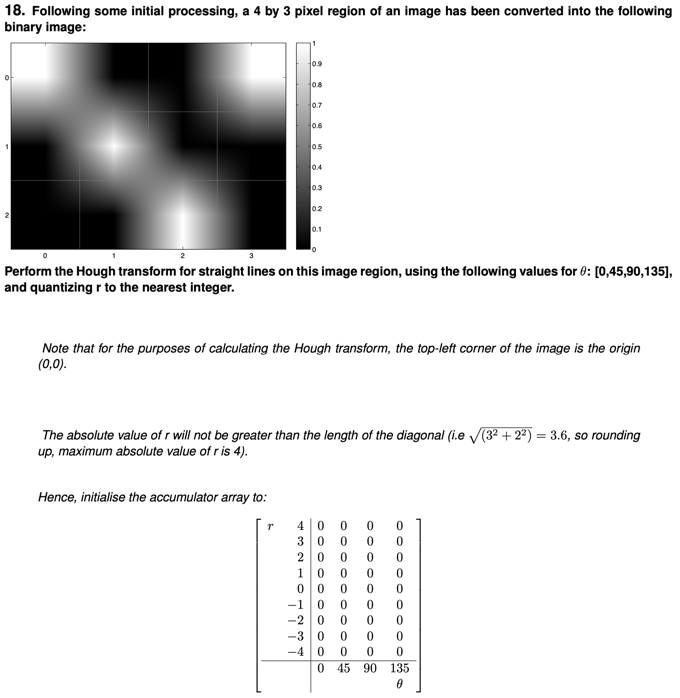

pixel_1 = [0 0];
pixel_2 = [1 1];
pixel_3 = [2 2];
pixel_4 = [3 0];

thetas = [0 45 90 135]

thetas =      0    45    90   135




cal_lines(pixel_1, thetas)

ans =      0     0     0     0



cal_lines(pixel_2, thetas)

ans =      1     0    -1    -1



cal_lines(pixel_3, thetas)

ans =      2     0    -2    -3



cal_lines(pixel_4, thetas)

ans =      0    -2    -3    -2



% Peak of accumulator array (3) is at (θ,r)=(45,0), 
% which corresponds to the line of three edge pixels in the image.

function out = cal_lines(pixel, thetas)
    array = zeros(1,length(thetas));

    for i = 1:length(thetas)
        array(i) = round(pixel(2)*cosd(thetas(i)) - pixel(1)*sind(thetas(i)), 0);
    end
    out = array;
end